baseline = model(10, ones(10, 1), ones(10, 1));
baseline = baseline.sde_euler;
baseline = baseline.monte_carlo(5000);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 6).


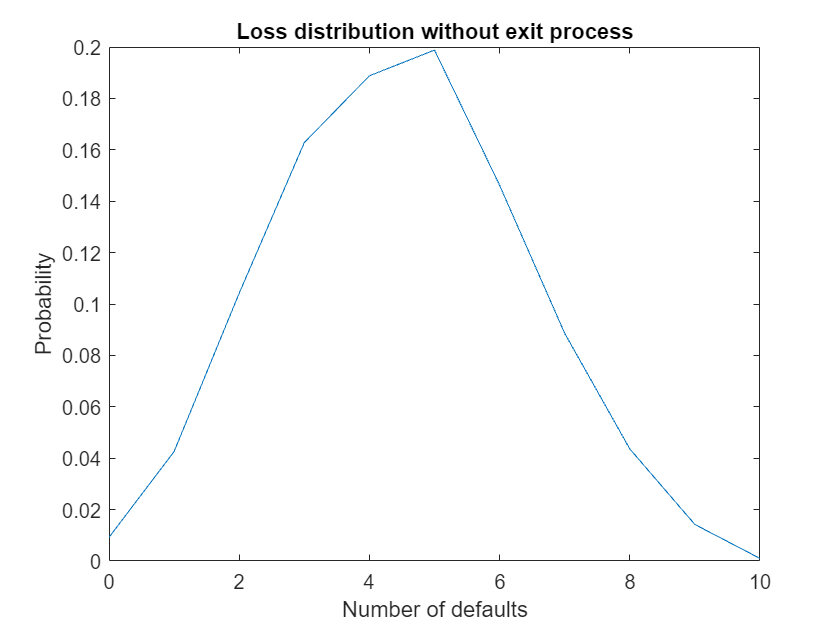

baseline.plot_loss;
title('Loss distribution without exit process')

fprintf("Probability of systemic failure: %.2f", baseline.probfail);

Probability of systemic failure: 0.03

Banks that have log monetary reserves less than $\eta$ are removed from the interbank network.

exit_model = baseline;
exit_model.A = ones(exit_model.N, exit_model.N);
exit_model = exit_model.adaptive_network(exit_model.eta);
exit_model = exit_model.sde_euler;
exit_model = exit_model.monte_carlo(5000);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 6).


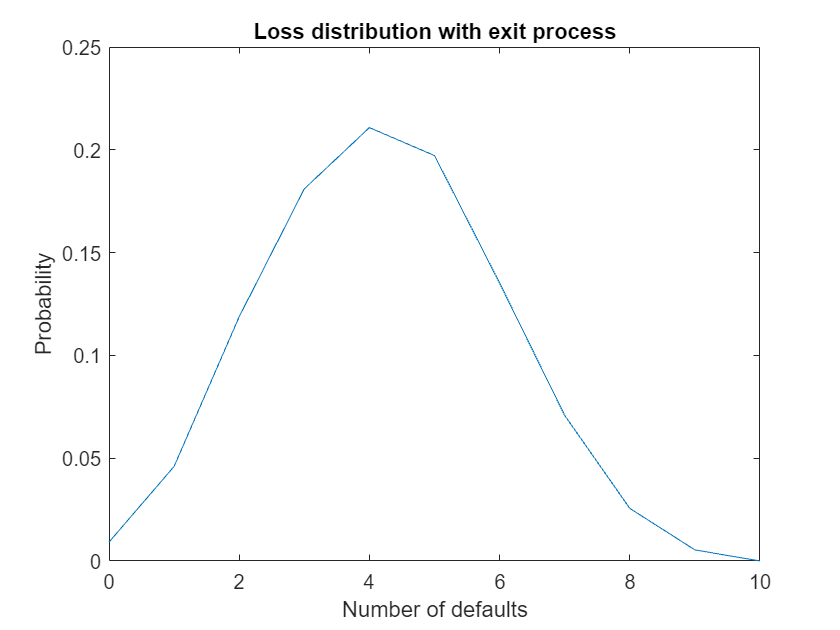

exit_model.plot_loss;
title('Loss distribution with exit process')

fprintf("Probability of systemic failure: %.2f", exit_model.probfail);

Probability of systemic failure: 0.03

baseline2 = exit_model;
baseline2 = baseline2.adaptive_network(-0.35);
baseline2 = baseline2.sde_euler;
baseline2 = baseline2.monte_carlo(500);

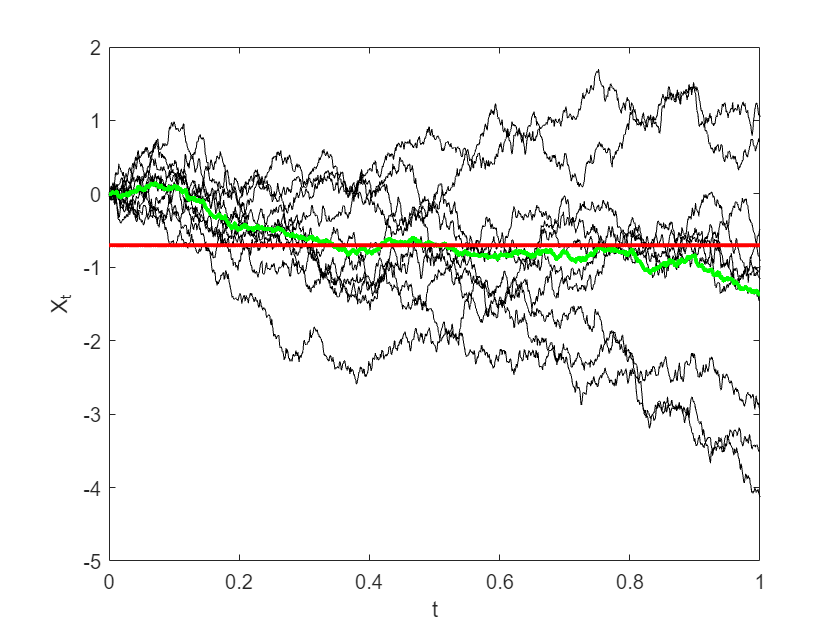

baseline2.plot_trajectory;

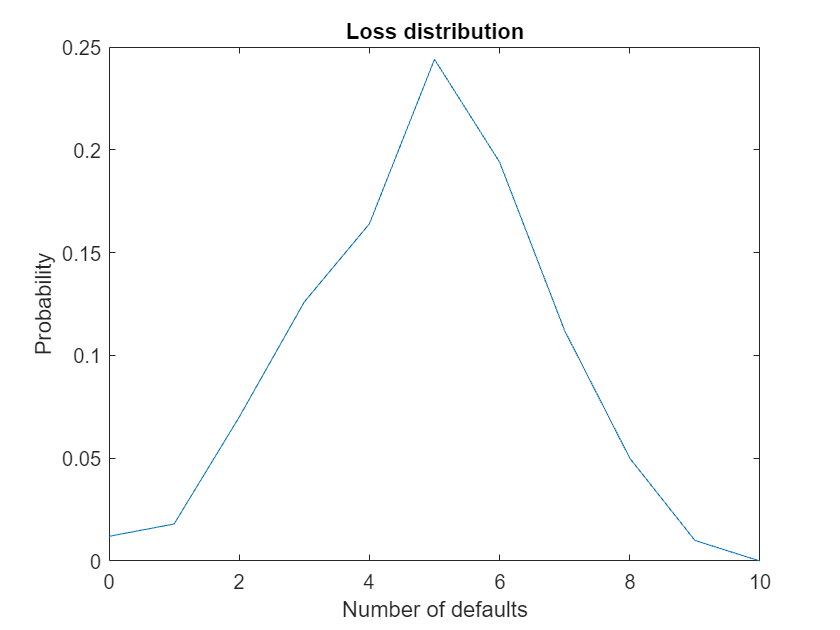

baseline2.plot_loss;

fprintf("Probability of systemic failure: %.2f", baseline2.probfail);

Probability of systemic failure: 0.13

When all banks are the same, removing banks too early can be slightly bad. These banks are left to fend for themselves and are more likely to fail. Next, do experiments with strong and weak banks...

groupA = model( ...
    10, ...
    [repelem(1, 2, 1); repelem(10, 5, 1); repelem(100, 3, 1)], ...
    [repelem(2, 2, 1); repelem(1, 5, 1); repelem(0.5, 3, 1)] ...
    );
groupA.A = ones(groupA.N);
groupA = groupA.adaptive_network(groupA.eta);
groupA = groupA.sde_euler;
groupA = groupA.monte_carlo(5000);

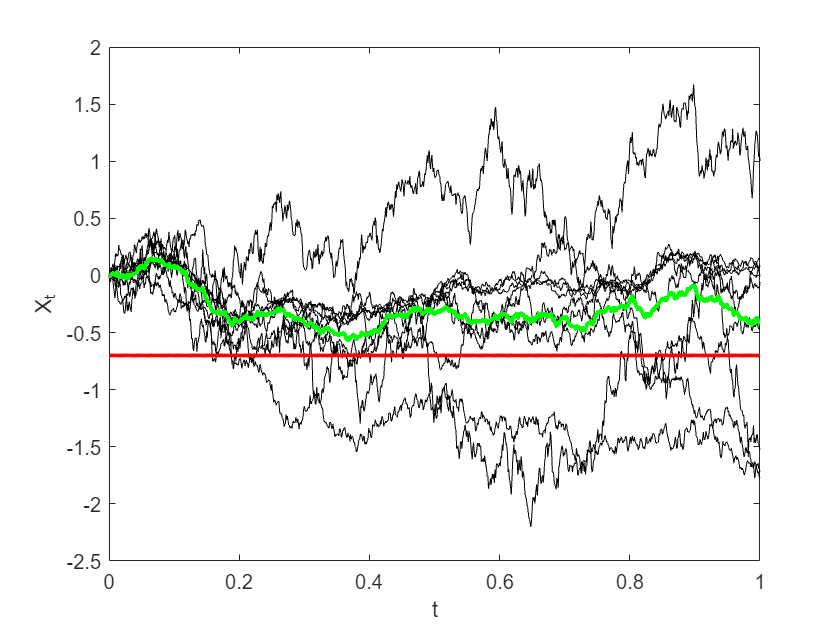

groupA.plot_trajectory;

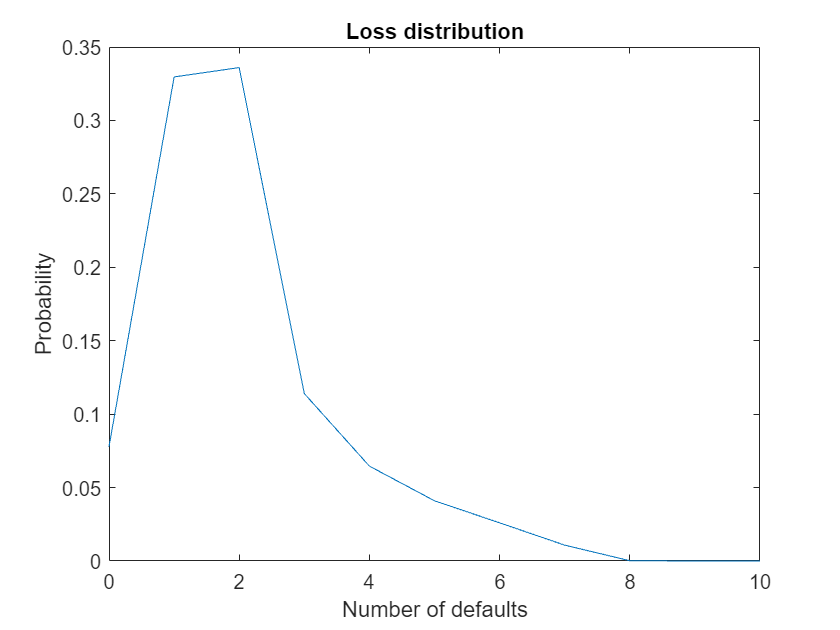

groupA.plot_loss;

fprintf("Probability of systemic failure: %.2f", groupA.probfail);

Probability of systemic failure: 0.07

groupA_early = model( ...
    10, ...
    [repelem(1, 2, 1); repelem(10, 5, 1); repelem(100, 3, 1)], ...
    [repelem(2, 2, 1); repelem(1, 5, 1); repelem(0.5, 3, 1)] ...
    );
groupA_early.A = ones(groupA_early.N);
groupA_early = groupA_early.adaptive_network(-0.35);
groupA_early = groupA_early.sde_euler;
groupA_early = groupA_early.monte_carlo(5000);

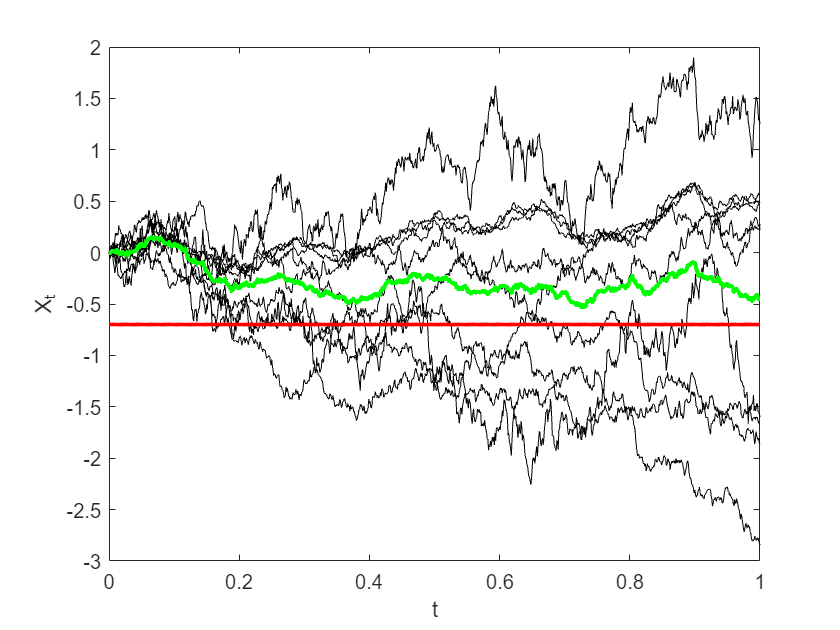

groupA_early.plot_trajectory;

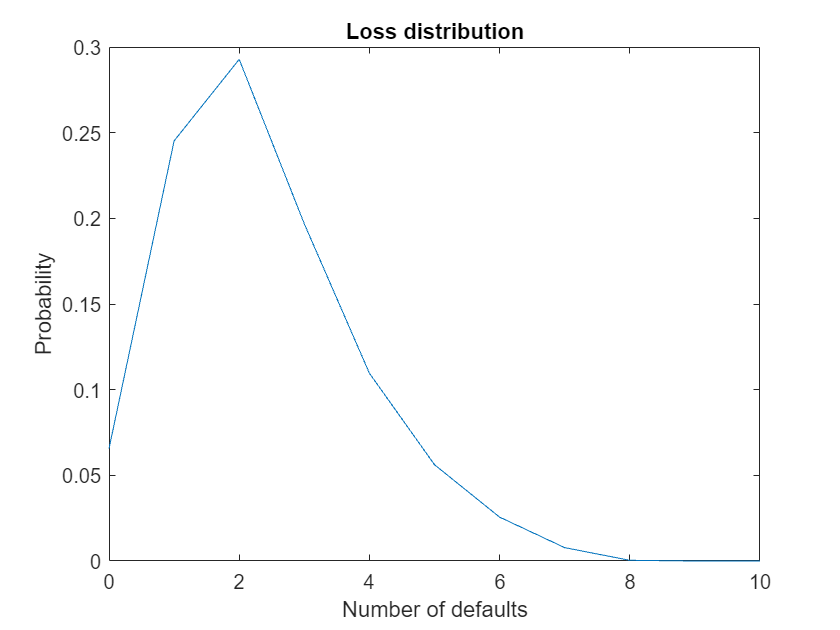

groupA_early.plot_loss;

fprintf("Probability of systemic failure: %.2f", groupA_early.probfail);

Probability of systemic failure: 0.04

# Group A - 8:1:1

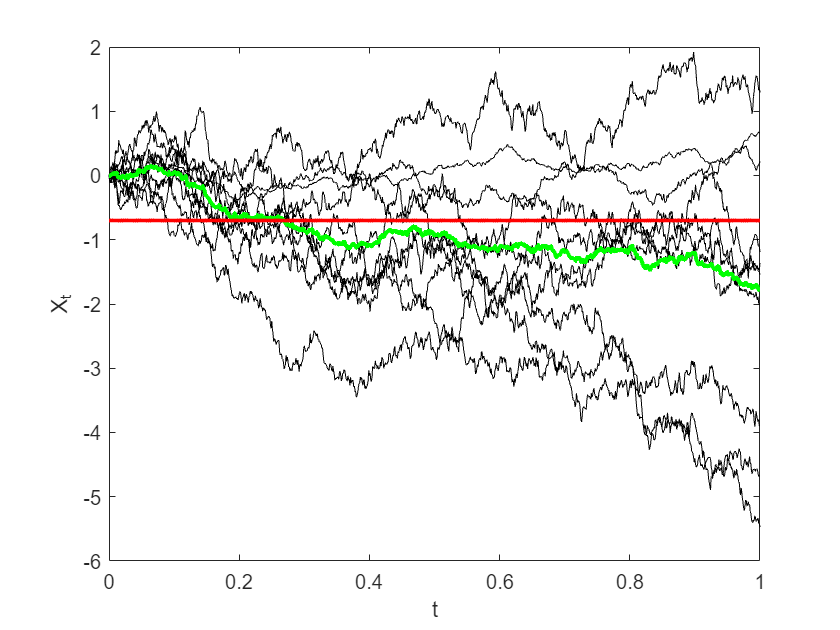

A1 = model( ...
    10, ...
    [repelem(1, 8, 1); repelem(10, 1, 1); repelem(100, 1, 1)], ...
    [repelem(2, 8, 1); repelem(1, 1, 1); repelem(0.5, 1, 1)] ...
    );
A1.A = ones(A1.N);
A1 = A1.adaptive_network_2(-0.7);
A1 = A1.sde_euler;
A1 = A1.monte_carlo(5000);

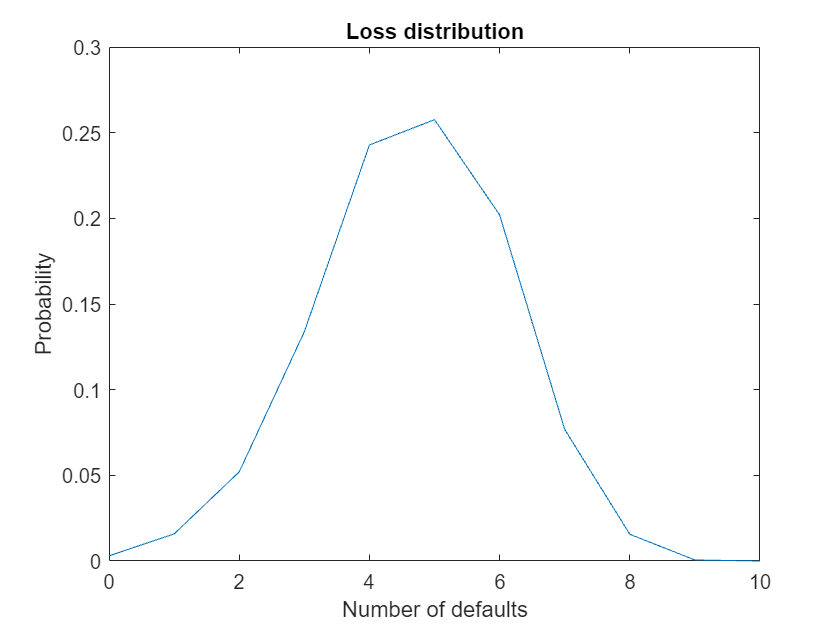

A1.plot_loss;

fprintf("Probability of systemic failure: %.2f", A1.probfail);

Probability of systemic failure: 0.18

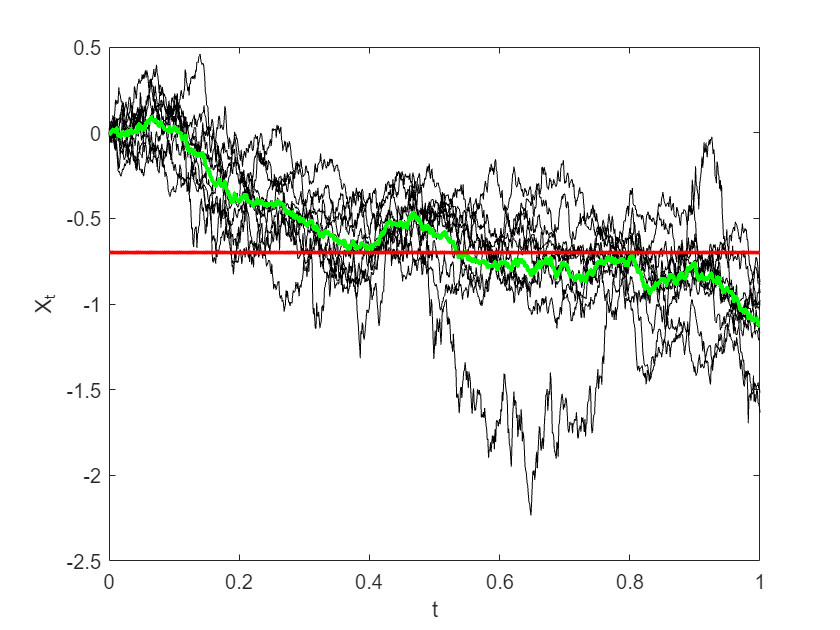

A2 = model( ...
    10, ...
    [repelem(1, 1, 1); repelem(10, 8, 1); repelem(100, 1, 1)], ...
    [repelem(2, 1, 1); repelem(1, 8, 1); repelem(0.5, 1, 1)] ...
    );
A2.A = ones(A2.N);
A2 = A2.adaptive_network_2(-0.7);
A2 = A2.sde_euler;
A2 = A2.monte_carlo(5000);

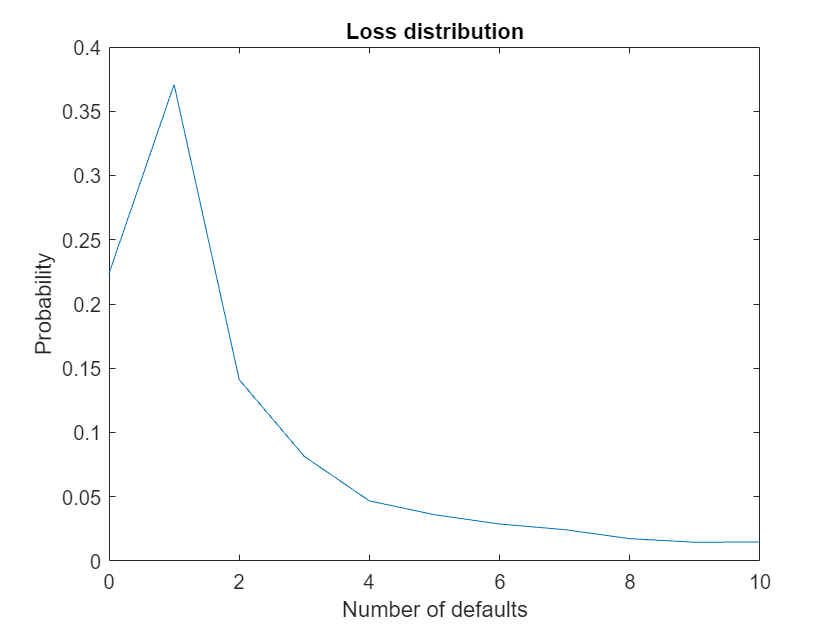

A2.plot_loss;

fprintf("Probability of systemic failure: %.2f", A2.probfail);

Probability of systemic failure: 0.05

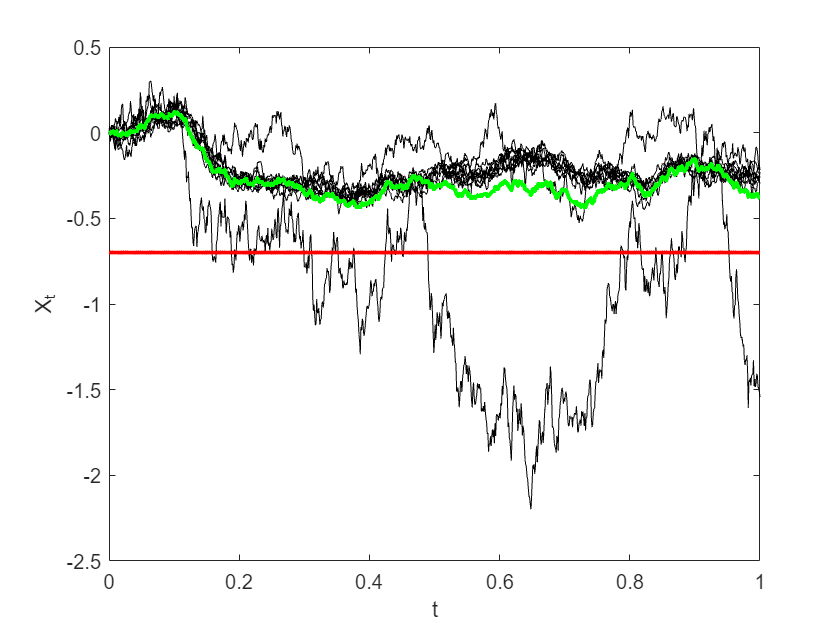

A3 = model( ...
    10, ...
    [repelem(1, 1, 1); repelem(10, 1, 1); repelem(100, 8, 1)], ...
    [repelem(2, 1, 1); repelem(1, 1, 1); repelem(0.5, 8, 1)] ...
    );
A3.A = ones(A3.N);
A3 = A3.adaptive_network_2(-0.7);
A3 = A3.sde_euler;
A3 = A3.monte_carlo(5000);

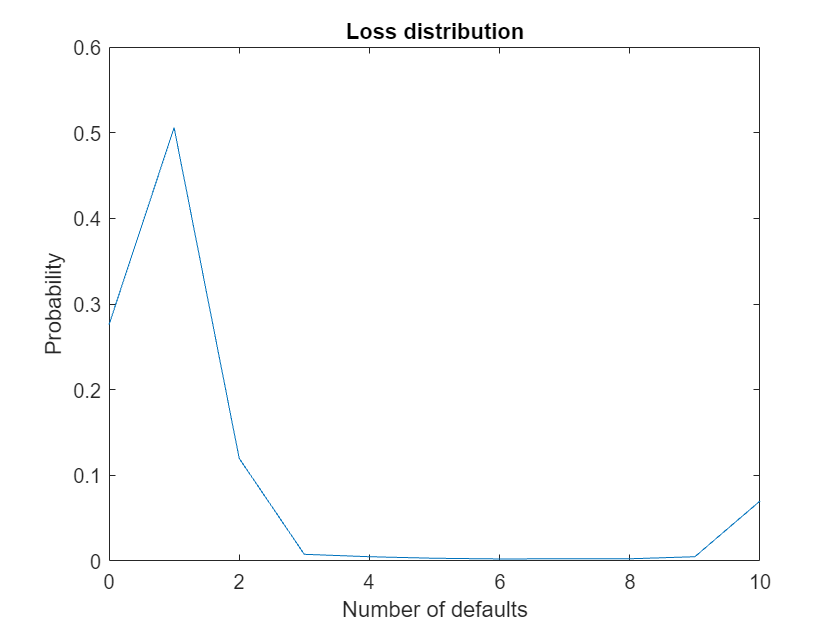

A3.plot_loss;

fprintf("Probability of systemic failure: %.2f", A3.probfail);

Probability of systemic failure: 0.12

# Group A - 8:1:1 - Remove all defaulted banks

A1_all = model( ...
    10, ...
    [repelem(1, 8, 1); repelem(10, 1, 1); repelem(100, 1, 1)], ...
    [repelem(2, 8, 1); repelem(1, 1, 1); repelem(0.5, 1, 1)] ...
    );
A1_all.A = ones(A1_all.N);
A1_all = A1_all.adaptive_network(-0.7);
A1_all = A1_all.sde_euler;
A1_all = A1_all.monte_carlo(5000);

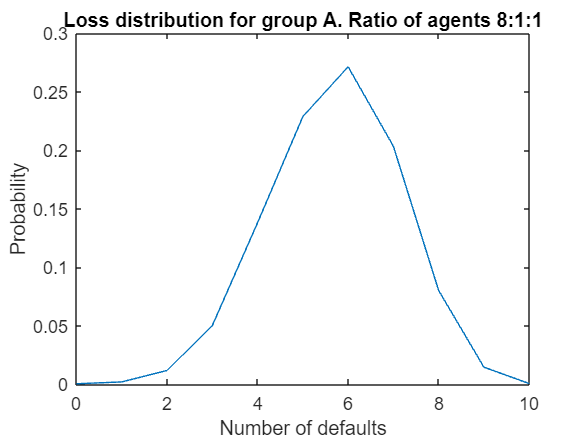

A1_all.plot_loss;
title('Loss distribution for group A. Ratio of agents 8:1:1')

fprintf("Probability of systemic failure: %.2f", A1_all.probfail);

Probability of systemic failure: 0.17

A2_all = model( ...
    10, ...
    [repelem(1, 1, 1); repelem(10, 8, 1); repelem(100, 1, 1)], ...
    [repelem(2, 1, 1); repelem(1, 8, 1); repelem(0.5, 1, 1)] ...
    );
A2_all.A = ones(A2_all.N);
A2_all = A2_all.adaptive_network(-0.7);
A2_all = A2_all.sde_euler;
A2_all = A2_all.monte_carlo(5000);

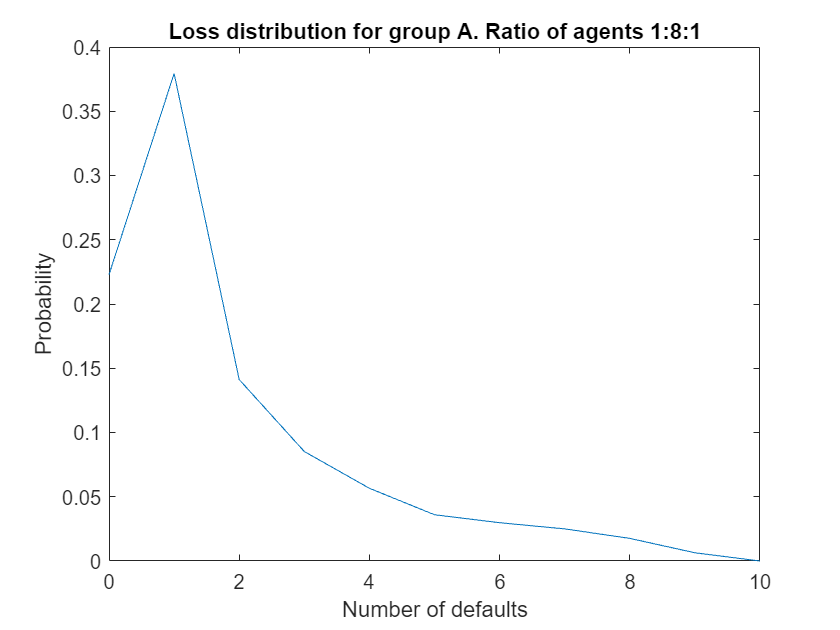

A2_all.plot_loss;
title('Loss distribution for group A. Ratio of agents 1:8:1')

fprintf("Probability of systemic failure: %.2f", A2_all.probfail);

Probability of systemic failure: 0.05

A3_all = model( ...
    10, ...
    [repelem(1, 1, 1); repelem(10, 1, 1); repelem(100, 8, 1)], ...
    [repelem(2, 1, 1); repelem(1, 1, 1); repelem(0.5, 8, 1)] ...
    );
A3_all.A = ones(A3_all.N);
A3_all = A3_all.adaptive_network(-0.7);
A3_all = A3_all.sde_euler;
A3_all = A3_all.monte_carlo(5000);

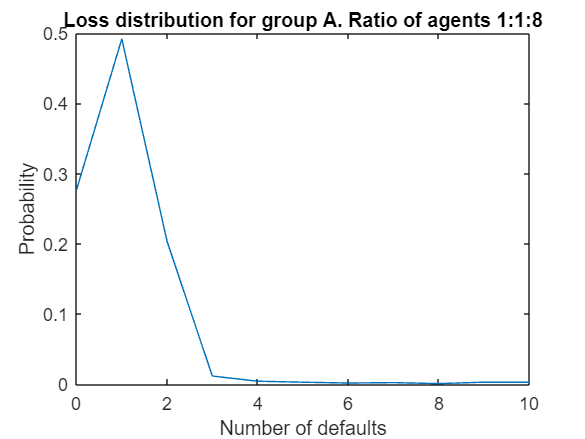

A3_all.plot_loss;
title('Loss distribution for group A. Ratio of agents 1:1:8')

fprintf("Probability of systemic failure: %.2f", A3_all.probfail);

Probability of systemic failure: 0.09